clear all

%%% GAUNTLET PRE-PLANNING %%%

% Creating meshgrid for gauntlet
x = -2.413:0.1:.6096; % Use dimensions of playpen in meters
y = -.3048:0.1:2.54; % Use dimensions of playpen in meters
[X,Y] = meshgrid(x,y);

% Create lines for box 1
x1 = -1.2192;
y1 = 1.4224;
x2 = -1.0668;
y2 = 1.1938;
slope = (y2-y1)/(x2-x1);
y0 = @(x0)slope*(x0-x1) + y1; 
fun = @(x0)log((X-x0).^2+(Y-y0(x0)).^2);
b1l1 = integral(fun,x1,x2,'ArrayValued',true);

fplot(y0,[x1,x2])
hold on;

x1 = -1.0668;
y1 = 1.1938;
x2 = -.762;
y2 = 1.4224;
slope = (y2-y1)/(x2-x1);
y0 = @(x0)slope*(x0-x1) + y1; 
fun = @(x0)log((X-x0).^2+(Y-y0(x0)).^2);
b1l2 = integral(fun,x1,x2,'ArrayValued',true);
fplot(y0,[x1,x2])

% Create lines for box 2
x1 = -.2413;
y1 = 1.0668;
x2 = -.2286;
y2 = .762;
slope = (y2-y1)/(x2-x1);
y0 = @(x0)slope*(x0-x1) + y1; 
fun = @(x0)log((X-x0).^2+(Y-y0(x0)).^2);
b2l1 = integral(fun,x1,x2,'ArrayValued',true);
fplot(y0,[x1,x2])

x1 = -.2286;
y1 = .762;
x2 = .1016;
y2 = .7874;
slope = (y2-y1)/(x2-x1);
y0 = @(x0)slope*(x0-x1) + y1; 
fun = @(x0)log((X-x0).^2+(Y-y0(x0)).^2);
b2l2 = integral(fun,x1,x2,'ArrayValued',true);
fplot(y0,[x1,x2])

% Create lines for circle
cx = -.3302;
cy = 1.8034;
radius = 0.27;
fun = @(theta)log((X-(radius*cos(theta)+cx)).^2+(Y-(radius*sin(theta)+cy)).^2);
c = -integral(fun,0,2*pi,'ArrayValued',true);

Z = (3*b1l1+1.7*b1l2+40*b2l1+b2l2)+.7*c;

[FX,FY] = gradient(Z);

TIME_STEP = 2; % in seconds
INITIAL_LOCATION = [-.6,.15]; % in meters from the origin
INITIAL_HEADING = pi/2; % in radians from the x-axis
MAX_SPEED = 0.1;
STOP_THRESHOLD = 8.44; % threshold when NEATO will stop
MAX_RUN_TIME = 10; % maximum seconds to drive NEATO
d = 0.24; % NEATO wheelbase size

x0 = INITIAL_LOCATION(1);
y0 = INITIAL_LOCATION(2);
max_distance = MAX_SPEED*TIME_STEP;

current_theta = INITIAL_HEADING;
current_x = x0;
current_y = y0;
commands = zeros(MAX_RUN_TIME/TIME_STEP,2);
step = 1;

%for debugging
points = zeros(MAX_RUN_TIME/TIME_STEP,2);

for test = 1:40
    points(test,:) = [current_x,current_y];
    
    % Compute direction of steepest descent  
    [xindex,yindex] = nearestIndex(current_x,current_y,x,y);
    
    fx = FX(yindex,xindex);
    fy = FY(yindex,xindex);
    g = sqrt(fx^2 + fy^2);
    
    z_value = Z(yindex,xindex);
    if z_value > STOP_THRESHOLD
        break
    end
    
    if fy >= 0
        desired_theta = acos(dot([1,0],[fx,fy])/norm([fx,fy]));
    elseif fy < 0
        desired_theta = 2*pi-acos(dot([1,0],[fx,fy])/norm([fx,fy]));
    end
        
    dtheta = desired_theta-current_theta;
    % Compute angular velocity for time step
    omega = dtheta/TIME_STEP; % in radians/s
    
    % Compute wheel commands
    V_L = double(MAX_SPEED - omega*d/2);
    V_R = double(MAX_SPEED + omega*d/2);
    commands(step,1) = V_L;
    commands(step,2) = V_R;
    
    % Find next point
    [dx,dy] = pol2cart(desired_theta,max_distance);
    
    % Update variables
    current_x = current_x + dx;
    current_y = current_y + dy;
    current_theta = current_theta + dtheta;
    step = step + 1;

end

%%% BRIDGE OF DEATH PRE-PLANNING %%%
% Set up symbolic functions
syms r(t) v(t) v_mag(t) omega(t)

% Set parameters
d = 0.26;

a = 0.4;
L = 0.4;
b = 1;
c = 0.13;

% Generate position function
x = -2*a*((L-cos(c*t))*cos(c*t) + (1-L));
y = 2*a*(L-cos(c*t))*sin(c*t);

r(t) = [x y 0];

% Find velocity functions
v(t) = diff(r(t),t);
v_mag(t) = norm(v(t));
T = v(t)./v_mag(t);
w(t) = cross(T,diff(T,t));
omega = w(t);
omega(t) = omega(3)

$$omega(t) = \begin{array}{l} -\frac{\left(\frac{\sigma_{3}}{\sqrt{\sigma_{5}}}-\frac{\sigma_{6}\,\sigma_{1}}{\sigma_{2}}\right)\,\left(\frac{13\,\sigma_{8}\,\left(\frac{4\,\sigma_{8}}{5}-\frac{8}{25}\right)}{100}-\frac{13\,{\sigma_{9}}^{2}}{125}\right)}{\sqrt{\sigma_{5}}}-\frac{\left(\frac{\sigma_{4}}{\sqrt{\sigma_{5}}}+\frac{\left(\frac{13\,\sigma_{8}\,\left(\frac{4\,\sigma_{8}}{5}-\frac{8}{25}\right)}{100}-\frac{13\,{\sigma_{9}}^{2}}{125}\right)\,\sigma_{1}}{\sigma_{2}}\right)\,\sigma_{6}}{\sqrt{\sigma_{5}}}\\ \mathrm{where}\\ \sigma_{1}=2\,\left|\sigma_{6}\right|\,\mathrm{sign}\left(\sigma_{6}\right)\,\sigma_{3}+2\,\left|\sigma_{7}\right|\,\mathrm{sign}\left(\sigma_{7}\right)\,\sigma_{4}\\ \sigma_{2}=2\,{\sigma_{5}}^{3/2}\\ \sigma_{3}=\frac{169\,\sigma_{8}\,\left(\sigma_{8}-\frac{2}{5}\right)}{12500}+\frac{169\,{\sigma_{8}}^{2}}{12500}-\frac{169\,{\sigma_{9}}^{2}}{6250}\\ \sigma_{4}=\frac{169\,\sigma_{9}\,\left(\frac{4\,\sigma_{8}}{5}-\frac{8}{25}\right)}{10000}+\frac{507\,\sigma_{8}\,\sigma_{9}}{12500}\\ \sigma_{5}={\left|\sigma_{7}\right|}^{2}+{\left|\sigma_{6}\right|}^{2}\\ \sigma_{6}=\frac{13\,\sigma_{9}\,\left(\sigma_{8}-\frac{2}{5}\right)}{125}+\frac{13\,\sigma_{8}\,\sigma_{9}}{125}\\ \sigma_{7}=\frac{13\,{\sigma_{9}}^{2}}{125}-\frac{13\,\sigma_{8}\,\left(\frac{4\,\sigma_{8}}{5}-\frac{8}{25}\right)}{100}\\ \sigma_{8}=\cos\left(\frac{13\,t}{100}\right)\\ \sigma_{9}=\sin\left(\frac{13\,t}{100}\right) \end{array}$$


n = 1.07*pi/c;
m = 165*2;
% Generate set of 't's
t = linspace(1,n,m)';

% Find V_L and V_R
V_L = double(v_mag(t) - omega(t) * (d/2));
V_R = double(v_mag(t) + omega(t) * (d/2));

%%% MOVE NEATO %%%
% Check alignment on bridge
% Requires stilts on wheels

pub = rospublisher('/raw_vel');
msg = rosmessage(pub);

% Publish commands for bridge
for i = 1:length(t)
    V_L(i), V_R(i)
    msg.Data = [V_L(i), V_R(i)];
    send(pub,msg)
    pause(t(2)-t(1))
end

ans = 0.1077

ans = 0.0183

ans = 0.1077

ans = 0.0184

ans = 0.1078

ans = 0.0186

ans = 0.1078

ans = 0.0187

ans = 0.1078

ans = 0.0189

ans = 0.1079

ans = 0.0191

ans = 0.1079

ans = 0.0193

ans = 0.1080

ans = 0.0195

ans = 0.1080

ans = 0.0197

ans = 0.1081

ans = 0.0199

ans = 0.1082

ans = 0.0202

ans = 0.1082

ans = 0.0204

ans = 0.1083

ans = 0.0207

ans = 0.1084

ans = 0.0209

ans = 0.1084

ans = 0.0212

ans = 0.1085

ans = 0.0215

ans = 0.1086

ans = 0.0218

ans = 0.1087

ans = 0.0220

ans = 0.1088

ans = 0.0223

ans = 0.1089

ans = 0.0227

ans = 0.1090

ans = 0.0230

ans = 0.1091

ans = 0.0233

ans = 0.1092

ans = 0.0236

ans = 0.1093

ans = 0.0239

ans = 0.1094

ans = 0.0243

ans = 0.1095

ans = 0.0246

ans = 0.1096

ans = 0.0250

ans = 0.1097

ans = 0.0253

ans = 0.1098

ans = 0.0257

ans = 0.1100

ans = 0.0261

ans = 0.1101

ans = 0.0265

ans = 0.1102

ans = 0.0268

ans = 0.1104

ans = 0.0272

ans = 0.1105

ans = 0.0276

ans = 0.1107

ans = 0.0280

ans = 0.1108

ans = 0.0284

ans = 0.1110

ans = 0.0288

ans = 0.1111

ans = 0.0292

ans = 0.1113

ans = 0.0297

ans = 0.1114

ans = 0.0301

ans = 0.1116

ans = 0.0305

ans = 0.1118

ans = 0.0309

ans = 0.1120

ans = 0.0314

ans = 0.1121

ans = 0.0318

ans = 0.1123

ans = 0.0322

ans = 0.1125

ans = 0.0327

ans = 0.1127

ans = 0.0331

ans = 0.1129

ans = 0.0336

ans = 0.1131

ans = 0.0340

ans = 0.1133

ans = 0.0345

ans = 0.1135

ans = 0.0349

ans = 0.1137

ans = 0.0354

ans = 0.1139

ans = 0.0359

ans = 0.1142

ans = 0.0363

ans = 0.1144

ans = 0.0368

ans = 0.1146

ans = 0.0373

ans = 0.1148

ans = 0.0377

ans = 0.1151

ans = 0.0382

ans = 0.1153

ans = 0.0387

ans = 0.1155

ans = 0.0392

ans = 0.1158

ans = 0.0396

ans = 0.1160

ans = 0.0401

ans = 0.1163

ans = 0.0406

ans = 0.1165

ans = 0.0411

ans = 0.1168

ans = 0.0416

ans = 0.1170

ans = 0.0420

ans = 0.1173

ans = 0.0425

ans = 0.1175

ans = 0.0430

ans = 0.1178

ans = 0.0435

ans = 0.1181

ans = 0.0440

ans = 0.1183

ans = 0.0445

ans = 0.1186

ans = 0.0450

ans = 0.1189

ans = 0.0455

ans = 0.1192

ans = 0.0459

ans = 0.1195

ans = 0.0464

ans = 0.1197

ans = 0.0469

ans = 0.1200

ans = 0.0474

ans = 0.1203

ans = 0.0479

ans = 0.1206

ans = 0.0484

ans = 0.1209

ans = 0.0489

ans = 0.1212

ans = 0.0494

ans = 0.1215

ans = 0.0499

ans = 0.1218

ans = 0.0504

ans = 0.1221

ans = 0.0509

ans = 0.1224

ans = 0.0514

ans = 0.1227

ans = 0.0519

ans = 0.1230

ans = 0.0524

ans = 0.1233

ans = 0.0528

ans = 0.1236

ans = 0.0533

ans = 0.1240

ans = 0.0538

ans = 0.1243

ans = 0.0543

ans = 0.1246

ans = 0.0548

ans = 0.1249

ans = 0.0553

ans = 0.1252

ans = 0.0558

ans = 0.1256

ans = 0.0563

ans = 0.1259

ans = 0.0568

ans = 0.1262

ans = 0.0573

ans = 0.1265

ans = 0.0577

ans = 0.1269

ans = 0.0582

ans = 0.1272

ans = 0.0587

ans = 0.1275

ans = 0.0592

ans = 0.1279

ans = 0.0597

ans = 0.1282

ans = 0.0602

ans = 0.1285

ans = 0.0607

ans = 0.1289

ans = 0.0611

ans = 0.1292

ans = 0.0616

ans = 0.1295

ans = 0.0621

ans = 0.1299

ans = 0.0626

ans = 0.1302

ans = 0.0631

ans = 0.1305

ans = 0.0635

ans = 0.1309

ans = 0.0640

ans = 0.1312

ans = 0.0645

ans = 0.1316

ans = 0.0650

ans = 0.1319

ans = 0.0654

ans = 0.1322

ans = 0.0659

ans = 0.1326

ans = 0.0664

ans = 0.1329

ans = 0.0668

ans = 0.1333

ans = 0.0673

ans = 0.1336

ans = 0.0678

ans = 0.1340

ans = 0.0682

ans = 0.1343

ans = 0.0687

ans = 0.1347

ans = 0.0692

ans = 0.1350

ans = 0.0696

ans = 0.1353

ans = 0.0701

ans = 0.1357

ans = 0.0706

ans = 0.1360

ans = 0.0710

ans = 0.1364

ans = 0.0715

ans = 0.1367

ans = 0.0719

ans = 0.1371

ans = 0.0724

ans = 0.1374

ans = 0.0728

ans = 0.1378

ans = 0.0733

ans = 0.1381

ans = 0.0737

ans = 0.1385

ans = 0.0742

ans = 0.1388

ans = 0.0746

ans = 0.1391

ans = 0.0751

ans = 0.1395

ans = 0.0755

ans = 0.1398

ans = 0.0759

ans = 0.1402

ans = 0.0764

ans = 0.1405

ans = 0.0768

ans = 0.1409

ans = 0.0773

ans = 0.1412

ans = 0.0777

ans = 0.1415

ans = 0.0781

ans = 0.1419

ans = 0.0785

ans = 0.1422

ans = 0.0790

ans = 0.1426

ans = 0.0794

ans = 0.1429

ans = 0.0798

ans = 0.1432

ans = 0.0803

ans = 0.1436

ans = 0.0807

ans = 0.1439

ans = 0.0811

ans = 0.1443

ans = 0.0815

ans = 0.1446

ans = 0.0819

ans = 0.1449

ans = 0.0823

ans = 0.1453

ans = 0.0828

ans = 0.1456

ans = 0.0832

ans = 0.1459

ans = 0.0836

ans = 0.1463

ans = 0.0840

ans = 0.1466

ans = 0.0844

ans = 0.1469

ans = 0.0848

ans = 0.1472

ans = 0.0852

ans = 0.1476

ans = 0.0856

ans = 0.1479

ans = 0.0860

ans = 0.1482

ans = 0.0864

ans = 0.1486

ans = 0.0868

ans = 0.1489

ans = 0.0872

ans = 0.1492

ans = 0.0875

ans = 0.1495

ans = 0.0879

ans = 0.1498

ans = 0.0883

ans = 0.1502

ans = 0.0887

ans = 0.1505

ans = 0.0891

ans = 0.1508

ans = 0.0894

ans = 0.1511

ans = 0.0898

ans = 0.1514

ans = 0.0902

ans = 0.1517

ans = 0.0906

ans = 0.1520

ans = 0.0909

ans = 0.1523

ans = 0.0913

ans = 0.1527

ans = 0.0917

ans = 0.1530

ans = 0.0920

ans = 0.1533

ans = 0.0924

ans = 0.1536

ans = 0.0927

ans = 0.1539

ans = 0.0931

ans = 0.1542

ans = 0.0934

ans = 0.1545

ans = 0.0938

ans = 0.1548

ans = 0.0941

ans = 0.1551

ans = 0.0945

ans = 0.1553

ans = 0.0948

ans = 0.1556

ans = 0.0952

ans = 0.1559

ans = 0.0955

ans = 0.1562

ans = 0.0958

ans = 0.1565

ans = 0.0962

ans = 0.1568

ans = 0.0965

ans = 0.1571

ans = 0.0968

ans = 0.1573

ans = 0.0972

ans = 0.1576

ans = 0.0975

ans = 0.1579

ans = 0.0978

ans = 0.1582

ans = 0.0981

ans = 0.1585

ans = 0.0985

ans = 0.1587

ans = 0.0988

ans = 0.1590

ans = 0.0991

ans = 0.1593

ans = 0.0994

ans = 0.1595

ans = 0.0997

ans = 0.1598

ans = 0.1000

ans = 0.1601

ans = 0.1003

ans = 0.1603

ans = 0.1006

ans = 0.1606

ans = 0.1009

ans = 0.1608

ans = 0.1012

ans = 0.1611

ans = 0.1015

ans = 0.1613

ans = 0.1018

ans = 0.1616

ans = 0.1021

ans = 0.1618

ans = 0.1023

ans = 0.1621

ans = 0.1026

ans = 0.1623

ans = 0.1029

ans = 0.1626

ans = 0.1032

ans = 0.1628

ans = 0.1035

ans = 0.1631

ans = 0.1037

ans = 0.1633

ans = 0.1040

ans = 0.1635

ans = 0.1043

ans = 0.1638

ans = 0.1045

ans = 0.1640

ans = 0.1048

ans = 0.1642

ans = 0.1050

ans = 0.1644

ans = 0.1053

ans = 0.1647

ans = 0.1055

ans = 0.1649

ans = 0.1058

ans = 0.1651

ans = 0.1060

ans = 0.1653

ans = 0.1063

ans = 0.1655

ans = 0.1065

ans = 0.1657

ans = 0.1068

ans = 0.1659

ans = 0.1070

ans = 0.1662

ans = 0.1072

ans = 0.1664

ans = 0.1075

ans = 0.1666

ans = 0.1077

ans = 0.1668

ans = 0.1079

ans = 0.1670

ans = 0.1081

ans = 0.1672

ans = 0.1084

ans = 0.1673

ans = 0.1086

ans = 0.1675

ans = 0.1088

ans = 0.1677

ans = 0.1090

ans = 0.1679

ans = 0.1092

ans = 0.1681

ans = 0.1094

ans = 0.1683

ans = 0.1096

ans = 0.1685

ans = 0.1098

ans = 0.1686

ans = 0.1100

ans = 0.1688

ans = 0.1102

ans = 0.1690

ans = 0.1104

ans = 0.1691

ans = 0.1106

ans = 0.1693

ans = 0.1108

ans = 0.1695

ans = 0.1110

ans = 0.1696

ans = 0.1112

ans = 0.1698

ans = 0.1113

ans = 0.1700

ans = 0.1115

ans = 0.1701

ans = 0.1117

ans = 0.1703

ans = 0.1118

ans = 0.1704

ans = 0.1120

ans = 0.1706

ans = 0.1122

ans = 0.1707

ans = 0.1123

ans = 0.1708

ans = 0.1125

ans = 0.1710

ans = 0.1126

ans = 0.1711

ans = 0.1128

ans = 0.1713

ans = 0.1129

ans = 0.1714

ans = 0.1131

ans = 0.1715

ans = 0.1132

ans = 0.1716

ans = 0.1134

ans = 0.1718

ans = 0.1135

ans = 0.1719

ans = 0.1136

ans = 0.1720

ans = 0.1138

ans = 0.1721

ans = 0.1139

ans = 0.1722

ans = 0.1140

ans = 0.1723

ans = 0.1142

ans = 0.1724

ans = 0.1143

ans = 0.1726

ans = 0.1144

ans = 0.1727

ans = 0.1145

ans = 0.1728

ans = 0.1146

ans = 0.1729

ans = 0.1147

ans = 0.1729

ans = 0.1148

ans = 0.1730

ans = 0.1149

ans = 0.1731

ans = 0.1150

ans = 0.1732

ans = 0.1151

ans = 0.1733

ans = 0.1152

ans = 0.1734

ans = 0.1153

ans = 0.1735

ans = 0.1154

ans = 0.1735

ans = 0.1155

ans = 0.1736

ans = 0.1156

ans = 0.1737

ans = 0.1156

ans = 0.1737

ans = 0.1157

ans = 0.1738

ans = 0.1158

ans = 0.1739

ans = 0.1159

ans = 0.1739

ans = 0.1159

ans = 0.1740

ans = 0.1160

ans = 0.1740

ans = 0.1161

ans = 0.1741

ans = 0.1161

ans = 0.1741

ans = 0.1162

ans = 0.1742

ans = 0.1162

ans = 0.1742

ans = 0.1163

ans = 0.1743

ans = 0.1163

ans = 0.1743

ans = 0.1163

ans = 0.1744

ans = 0.1164

ans = 0.1744

ans = 0.1164

ans = 0.1744

ans = 0.1165

ans = 0.1744

ans = 0.1165

ans = 0.1745

ans = 0.1165

ans = 0.1745

ans = 0.1165

ans = 0.1745

ans = 0.1166

ans = 0.1745

ans = 0.1166

ans = 0.1745

ans = 0.1166

ans = 0.1746

ans = 0.1166

ans = 0.1746

ans = 0.1166

ans = 0.1746

ans = 0.1166

ans = 0.1746

ans = 0.1166

ans = 0.1746

ans = 0.1166

ans = 0.1746

ans = 0.1166

ans = 0.1746

ans = 0.1166

ans = 0.1746

ans = 0.1166

ans = 0.1745

ans = 0.1166

ans = 0.1745

ans = 0.1166

ans = 0.1745

ans = 0.1166

ans = 0.1745

ans = 0.1165

ans = 0.1745

ans = 0.1165

ans = 0.1745

ans = 0.1165

ans = 0.1744

ans = 0.1165

ans = 0.1744

ans = 0.1164

ans = 0.1744

ans = 0.1164

ans = 0.1743

ans = 0.1164

ans = 0.1743

ans = 0.1163

ans = 0.1742

ans = 0.1163

ans = 0.1742

ans = 0.1162

ans = 0.1742

ans = 0.1162

ans = 0.1741

ans = 0.1161

ans = 0.1741

ans = 0.1161

ans = 0.1740

ans = 0.1160

ans = 0.1739

ans = 0.1159

ans = 0.1739

ans = 0.1159


stop = rosmessage(pub);
stop.Data = [0, 0];
send(pub,stop)

% Turn to align with gauntlet
w = .45/2;
V_L = double(- w * (d/2));
V_R = double(  w * (d/2));
msg.Data = [V_L V_R];
send(pub,msg);
pause(2);
msg.Data = [0.0 0.0];
pause(1);

% Drive to gauntlet origin
msg.Data = [0.1 0.1];
send(pub,msg);
pause(15);
msg.Data = [0.0 0.0];

% Turn 90 degrees
rot_angle = -pi/4;
V_L = double(- rot_angle * (d/2));
V_R = double(  rot_angle * (d/2));
msg.Data = [V_L V_R];
send(pub,msg);
pause(2);
msg.Data = [0.0 0.0];
send(pub,msg);
pause(1);

%%% PUBLISH GAUNTLET COMMANDS %%%
for index = 1:numel(commands(:,1))
    command_x = commands(index,1);
    command_y = commands(index,2);
    
    msg.Data = [command_x command_y];
    send(pub,msg);
    pause(TIME_STEP);
end
msg.Data = [0 0];
send(pub,msg);
pause(0.5)

r_x_cmd = -flipud(commands(:,1));
r_y_cmd = -flipud(commands(:,2));

for index = 1:numel(commands(:,1))
    command_x = r_x_cmd(index);
    command_y = r_y_cmd(index);
    
    msg.Data = [command_x command_y];
    send(pub,msg);
    pause(TIME_STEP);
end
% Turn 90 degrees
w = pi/4;
V_L = double(- w * (d/2));
V_R = double(  w * (d/2));
msg.Data = [V_L V_R];
send(pub,msg);
pause(1.9);
msg.Data = [0.0 0.0];
send(pub,msg);
pause(1);

% Drive straight to mount doom
msg.Data = [0.1 0.1];
send(pub,msg);
pause(13)

%%% MOUNT DOOM %%%
xLevel = 0.18;

Fmsg = rosmessage(pub);
Fmsg.Data = [0.07,0.07];

TLmsg = rosmessage(pub);
TLmsg.Data = [-0.05,0.05];

TRmsg = rosmessage(pub);
TRmsg.Data = [0.05,-0.05];

Smsg = rosmessage(pub);
Smsg.Data = [0,0];

sub_accel = rossubscriber('/accel');

pause(1)

threshold = 0.035;

while(abs(sub_accel.LatestMessage.Data(1)) > xLevel)
    sub_accel.LatestMessage.Data
    send(pub,Fmsg);
    pause(0.1);
    if(abs(sub_accel.LatestMessage.Data(2)) > threshold)
        yMessage = sub_accel.LatestMessage.Data(2);

        if yMessage > 0
            while(abs(sub_accel.LatestMessage.Data(2)) > threshold)
            send(pub,TLmsg);
            end
        end

        if yMessage < 0
            while(abs(sub_accel.LatestMessage.Data(2)) > threshold)
            send(pub,TRmsg);
            end
        end        
    end
end

ans = 3×1 single column vector
    0.2460
    0.2150
    0.8940


ans = 3×1 single column vector
    0.3920
    0.0330
    0.8620


ans = 3×1 single column vector
    0.3920
    0.0330
    0.8620


ans = 3×1 single column vector
    0.3900
    0.0210
    0.8600


ans = 3×1 single column vector
    0.3830
    0.0090
    0.8620


ans = 3×1 single column vector
    0.3860
   -0.0060
    0.8670


ans = 3×1 single column vector
    0.3930
   -0.0200
    0.8580


ans = 3×1 single column vector
    0.3930
   -0.0200
    0.8580


ans = 3×1 single column vector
    0.4070
   -0.0280
    0.8570


ans = 3×1 single column vector
    0.4150
   -0.0310
    0.8440


ans = 3×1 single column vector
    0.4350
   -0.0330
    0.8320


ans = 3×1 single column vector
    0.4350
   -0.0330
    0.8320


ans = 3×1 single column vector
    0.5040
   -0.0300
    0.7940


ans = 3×1 single column vector
    0.5040
   -0.0300
    0.7940


ans = 3×1 single column vector
    0.5110
   -0.0170
    0.7900


ans = 3×1 single column vector
    0.5290
   -0.0050
    0.7810


ans = 3×1 single column vector
    0.5500
    0.0140
    0.7690


ans = 3×1 single column vector
    0.5500
    0.0140
    0.7690


ans = 3×1 single column vector
    0.5550
    0.0230
    0.7660


ans = 3×1 single column vector
    0.5460
    0.0220
    0.7710


ans = 3×1 single column vector
    0.5200
    0.0080
    0.7900


ans = 3×1 single column vector
    0.5200
    0.0080
    0.7900


ans = 3×1 single column vector
    0.5050
   -0.0130
    0.8010


ans = 3×1 single column vector
    0.5040
   -0.0270
    0.7990


ans = 3×1 single column vector
    0.4730
   -0.0300
    0.8100


ans = 3×1 single column vector
    0.4730
   -0.0300
    0.8100


ans = 3×1 single column vector
    0.4730
   -0.0200
    0.8110


ans = 3×1 single column vector
    0.4710
   -0.0100
    0.8190


ans = 3×1 single column vector
    0.4710
   -0.0100
    0.8190


ans = 3×1 single column vector
    0.4750
    0.0090
    0.8250


ans = 3×1 single column vector
    0.4700
    0.0130
    0.8290


ans = 3×1 single column vector
    0.4690
    0.0110
    0.8250


ans = 3×1 single column vector
    0.4690
    0.0110
    0.8250


ans = 3×1 single column vector
    0.4550
   -0.0110
    0.8250


ans = 3×1 single column vector
    0.4520
   -0.0250
    0.8230


ans = 3×1 single column vector
    0.4520
   -0.0250
    0.8230


ans = 3×1 single column vector
    0.4010
   -0.0330
    0.8500


ans = 3×1 single column vector
    0.4010
   -0.0330
    0.8500


ans = 3×1 single column vector
    0.4000
   -0.0220
    0.8540


ans = 3×1 single column vector
    0.3960
   -0.0100
    0.8590


ans = 3×1 single column vector
    0.3960
    0.0030
    0.8630


ans = 3×1 single column vector
    0.4000
    0.0100
    0.8620


ans = 3×1 single column vector
    0.4000
    0.0100
    0.8620


ans = 3×1 single column vector
    0.3980
    0.0100
    0.8600


ans = 3×1 single column vector
    0.3900
   -0.0090
    0.8580


ans = 3×1 single column vector
    0.3900
   -0.0090
    0.8580


ans = 3×1 single column vector
    0.3870
   -0.0210
    0.8540


ans = 3×1 single column vector
    0.3250
   -0.0310
    0.8820


ans = 3×1 single column vector
    0.3250
   -0.0310
    0.8820


ans = 3×1 single column vector
    0.3160
   -0.0180
    0.8850


ans = 3×1 single column vector
    0.3110
   -0.0110
    0.8890


ans = 3×1 single column vector
    0.3220
    0.0040
    0.8870


ans = 3×1 single column vector
    0.3220
    0.0040
    0.8870


ans = 3×1 single column vector
    0.3430
    0.0180
    0.8860


ans = 3×1 single column vector
    0.3620
    0.0340
    0.8770


ans = 3×1 single column vector
    0.3640
    0.0320
    0.8720


ans = 3×1 single column vector
    0.3670
    0.0190
    0.8620


ans = 3×1 single column vector
    0.3670
    0.0190
    0.8620


ans = 3×1 single column vector
    0.3680
    0.0030
    0.8520


ans = 3×1 single column vector
    0.3530
   -0.0220
    0.8620


ans = 3×1 single column vector
    0.2880
   -0.0030
    0.8930


ans = 3×1 single column vector
    0.2710
    0.0220
    0.9070


ans = 3×1 single column vector
    0.2590
    0.0320
    0.9040


ans = 3×1 single column vector
    0.2700
    0.0330
    0.8980


ans = 3×1 single column vector
    0.2700
    0.0330
    0.8980


ans = 3×1 single column vector
    0.2860
    0.0210
    0.8950


ans = 3×1 single column vector
    0.2980
    0.0090
    0.8910


ans = 3×1 single column vector
    0.2980
    0.0090
    0.8910


ans = 3×1 single column vector
    0.3170
   -0.0130
    0.8870


ans = 3×1 single column vector
    0.3280
   -0.0290
    0.8780


ans = 3×1 single column vector
    0.3280
   -0.0290
    0.8780


ans = 3×1 single column vector
    0.3250
   -0.0310
    0.8760


ans = 3×1 single column vector
    0.2860
   -0.0170
    0.8890


ans = 3×1 single column vector
    0.2690
   -0.0080
    0.9000


ans = 3×1 single column vector
    0.2690
   -0.0080
    0.9000


ans = 3×1 single column vector
    0.2630
   -0.0080
    0.9040


ans = 3×1 single column vector
    0.2670
   -0.0090
    0.8950


ans = 3×1 single column vector
    0.2670
   -0.0090
    0.8950


ans = 3×1 single column vector
    0.2620
   -0.0110
    0.9000


ans = 3×1 single column vector
    0.2550
   -0.0130
    0.9020


ans = 3×1 single column vector
    0.2570
   -0.0210
    0.9020


ans = 3×1 single column vector
    0.2570
   -0.0210
    0.9020


ans = 3×1 single column vector
    0.2620
   -0.0280
    0.9010


ans = 3×1 single column vector
    0.2520
   -0.0280
    0.8950


ans = 3×1 single column vector
    0.2520
   -0.0280
    0.8950


ans = 3×1 single column vector
    0.2260
   -0.0200
    0.9090


ans = 3×1 single column vector
    0.2190
   -0.0130
    0.9080


ans = 3×1 single column vector
    0.2110
   -0.0040
    0.9170


ans = 3×1 single column vector
    0.2110
   -0.0040
    0.9170


ans = 3×1 single column vector
    0.2250
    0.0050
    0.9100


ans = 3×1 single column vector
    0.2200
    0.0060
    0.9180


ans = 3×1 single column vector
    0.2170
         0
    0.9140


ans = 3×1 single column vector
    0.2130
   -0.0070
    0.9120


ans = 3×1 single column vector
    0.2130
   -0.0070
    0.9120


ans = 3×1 single column vector
    0.2300
   -0.0210
    0.9060


ans = 3×1 single column vector
    0.2450
   -0.0340
    0.9000


ans = 3×1 single column vector
    0.3160
   -0.0340
    0.8750


ans = 3×1 single column vector
    0.3160
   -0.0340
    0.8750


ans = 3×1 single column vector
    0.2980
    0.0050
    0.8860


ans = 3×1 single column vector
    0.2940
    0.0300
    0.9020


ans = 3×1 single column vector
    0.3040
    0.0310
    0.8920


ans = 3×1 single column vector
    0.3040
    0.0310
    0.8920


ans = 3×1 single column vector
    0.3060
    0.0260
    0.8910


ans = 3×1 single column vector
    0.3120
    0.0210
    0.8860


ans = 3×1 single column vector
    0.3390
    0.0020
    0.8710


ans = 3×1 single column vector
    0.3390
    0.0020
    0.8710


ans = 3×1 single column vector
    0.3770
   -0.0200
    0.8550


ans = 3×1 single column vector
    0.4050
   -0.0290
    0.8420


ans = 3×1 single column vector
    0.4020
   -0.0200
    0.8300


ans = 3×1 single column vector
    0.4020
   -0.0200
    0.8300


ans = 3×1 single column vector
    0.3550
   -0.0090
    0.8700


ans = 3×1 single column vector
    0.3340
   -0.0190
    0.8800


ans = 3×1 single column vector
    0.3230
   -0.0280
    0.8950


ans = 3×1 single column vector
    0.3370
   -0.0240
    0.8780


ans = 3×1 single column vector
    0.3370
   -0.0240
    0.8780


ans = 3×1 single column vector
    0.3650
   -0.0160
    0.8570


ans = 3×1 single column vector
    0.3700
   -0.0100
    0.8580


ans = 3×1 single column vector
    0.3790
    0.0100
    0.8650


ans = 3×1 single column vector
    0.3790
    0.0100
    0.8650


ans = 3×1 single column vector
    0.3800
    0.0290
    0.8690


ans = 3×1 single column vector
    0.3980
    0.0300
    0.8510


ans = 3×1 single column vector
    0.3980
    0.0300
    0.8510


ans = 3×1 single column vector
    0.3900
    0.0220
    0.8490


ans = 3×1 single column vector
    0.3900
    0.0220
    0.8490


ans = 3×1 single column vector
    0.3900
    0.0220
    0.8490


ans = 3×1 single column vector
    0.2450
    0.0330
    0.9210


ans = 3×1 single column vector
    0.2450
    0.0330
    0.9210


ans = 3×1 single column vector
    0.2730
    0.0270
    0.9060


ans = 3×1 single column vector
    0.3250
    0.0230
    0.8760


ans = 3×1 single column vector
    0.3650
    0.0050
    0.8600


ans = 3×1 single column vector
    0.3650
    0.0050
    0.8600


ans = 3×1 single column vector
    0.3820
   -0.0060
    0.8460


ans = 3×1 single column vector
    0.3500
   -0.0060
    0.8600


ans = 3×1 single column vector
    0.2930
    0.0110
    0.8890


ans = 3×1 single column vector
    0.2930
    0.0110
    0.8890


ans = 3×1 single column vector
    0.2540
    0.0240
    0.9100


ans = 3×1 single column vector
    0.2340
    0.0300
    0.9150


ans = 3×1 single column vector
    0.2200
    0.0330
    0.9200


ans = 3×1 single column vector
    0.2200
    0.0330
    0.9200


ans = 3×1 single column vector
    0.2110
    0.0330
    0.9190


ans = 3×1 single column vector
    0.1990
    0.0280
    0.9130


ans = 3×1 single column vector
    0.1990
    0.0280
    0.9130


ans = 3×1 single column vector
    0.2160
    0.0190
    0.9100


ans = 3×1 single column vector
    0.2270
    0.0040
    0.9050


ans = 3×1 single column vector
    0.2380
   -0.0190
    0.9010


ans = 3×1 single column vector
    0.2380
   -0.0190
    0.9010


ans = 3×1 single column vector
    0.2390
   -0.0330
    0.8820


ans = 3×1 single column vector
    0.2390
   -0.0330
    0.8820


ans = 3×1 single column vector
    0.2120
   -0.0230
    0.8950


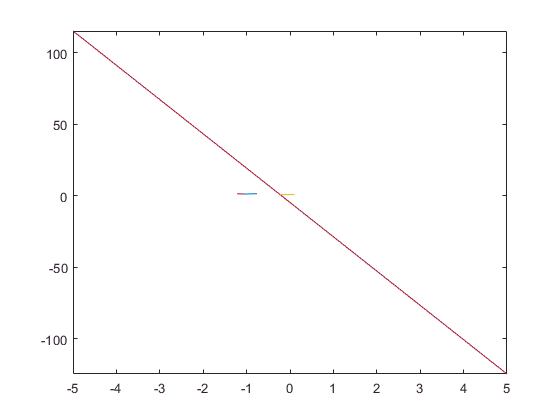


% Stop
Smsg = rosmessage(pub);
Smsg.Data = [0,0];
send(pub,Smsg);

function [xindex,yindex] = nearestIndex(px,py,xs,ys)
    %{
    ax = approx. of x
    yx = approx. of y
    px = x value to be approximated
    py = y value to be approximated
    xs = matrix of x values
    ys = matrix of y values
    %}
    xindex = dsearchn(xs',px);
    yindex = dsearchn(ys',py);
end